clc
clear
close all
[y,f]=audioread("ek_vaari_ya.wav");
y=y(800000:1500000,1);
%sound(y,f)
n=length(y)

n = 700001

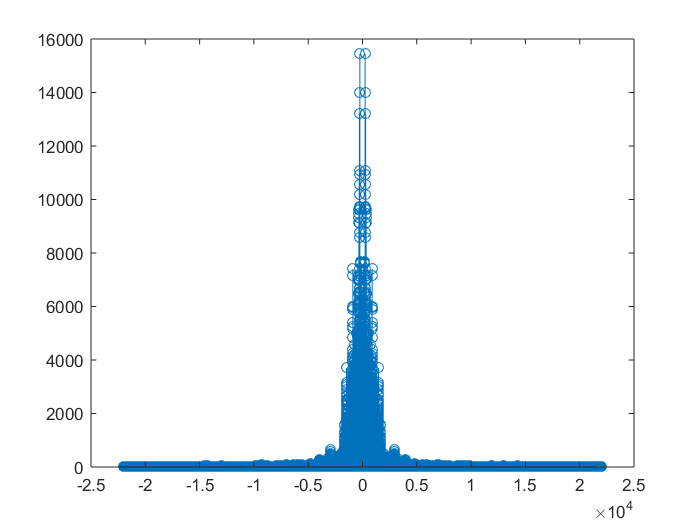

%ff=-f/2+0.5-8*f/n:f/n:f/2-0.5+7*f/n;
ff=-f/2:f/n:(f/2);
ff=ff(1:end-1);
Y=abs(fftshift(fft(y)));
stem(ff,Y)




A1=1

A1 = 1

A2=5

A2 = 5

A3=1

A3 = 1

A4=10

A4 = 10

alp = 50

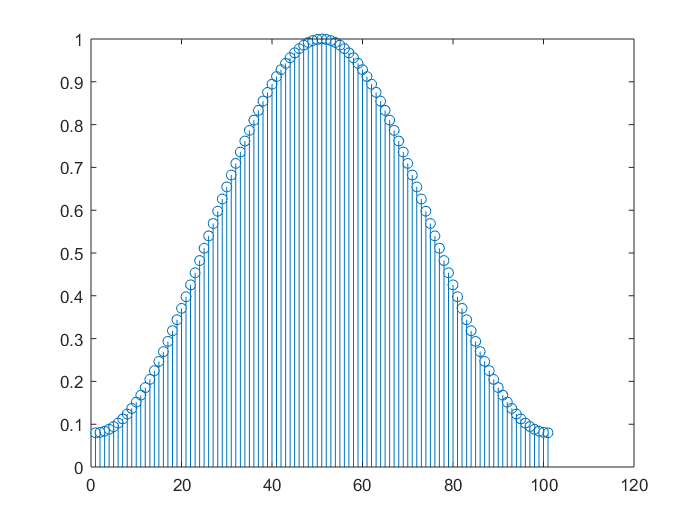

ans =      1   101


ans =      1   101


h1=Filters(101,"ham","high",0,625*2*pi/44100,50);

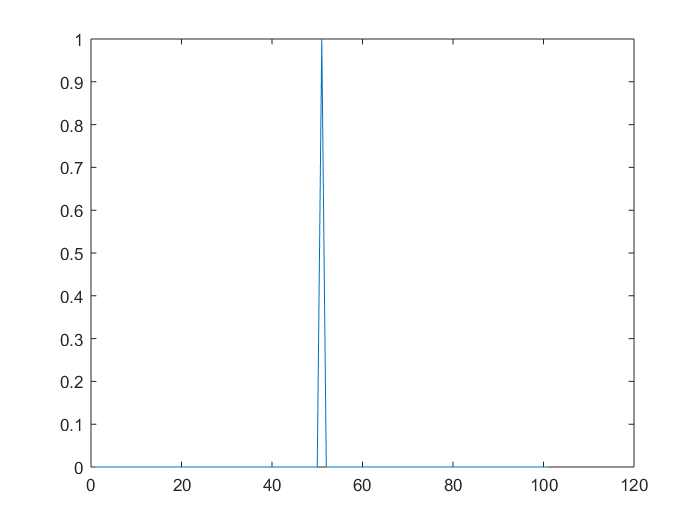

plot(h1)

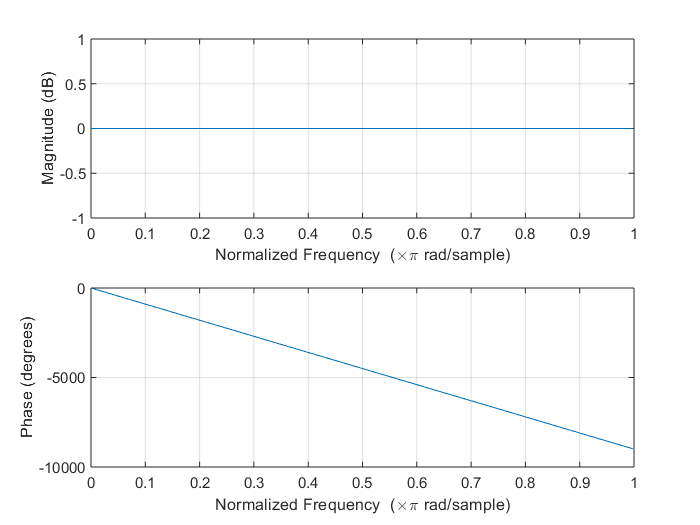

freqz(h1)

alp = 50

ans =      1   101


ans =      1   101


h2=Filters(101,"ham","bandpass",625*2*pi/44100,1250*2*pi/44100,50);

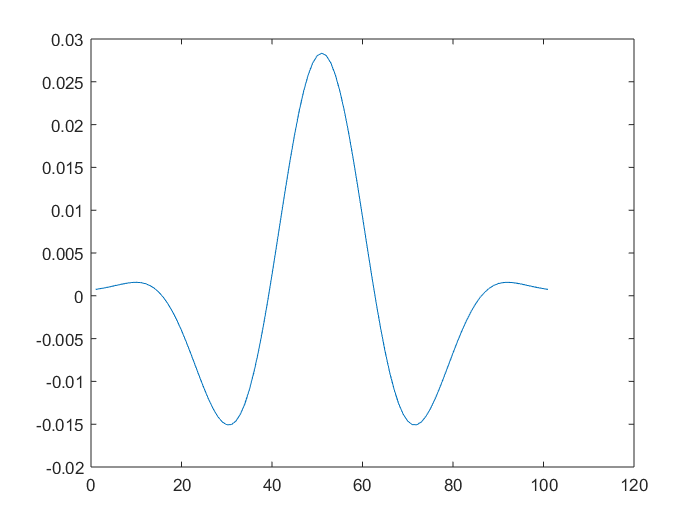

plot(h2)

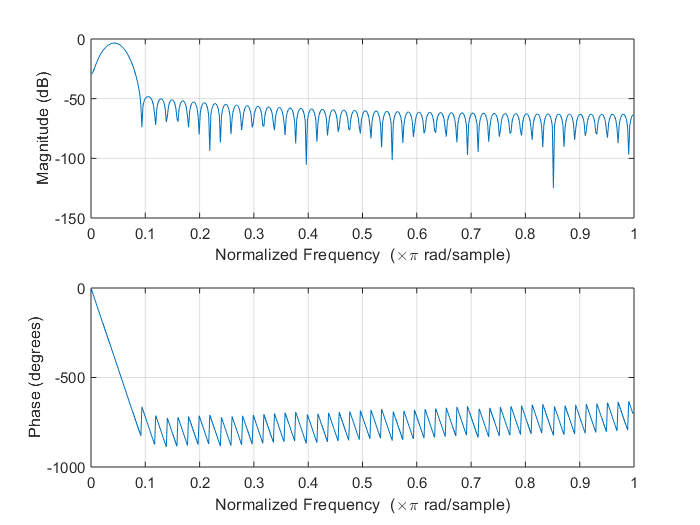

freqz(h2)

alp = 50

ans =      1   101


ans =      1   101


h3=Filters(101,"ham","bandpass",1250*2*pi/44100,2500*2*pi/44100,50);

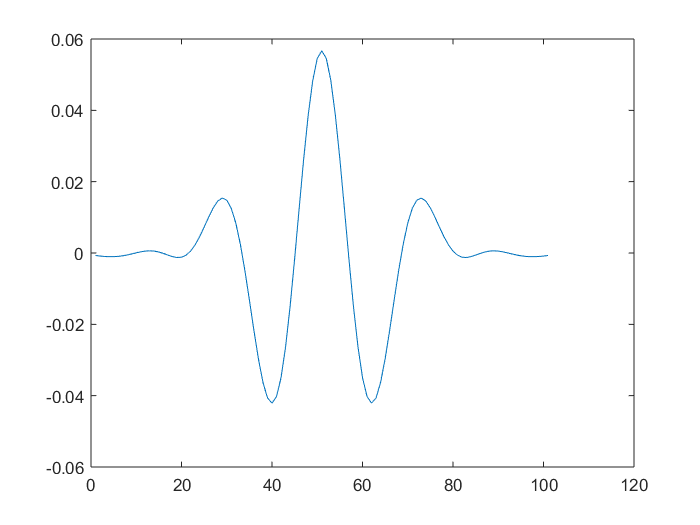

plot(h3)

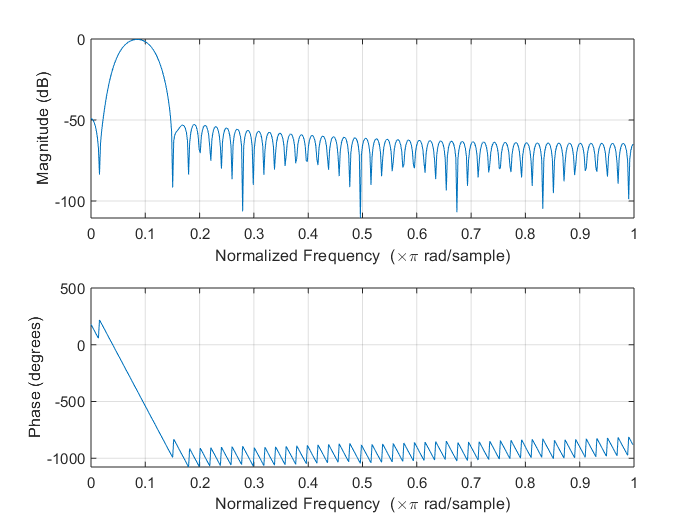

freqz(h3)

alp = 50

ans =      1   101


ans =      1   101


h4=Filters(101,"ham","low",2500*2*pi/44100,pi,50);

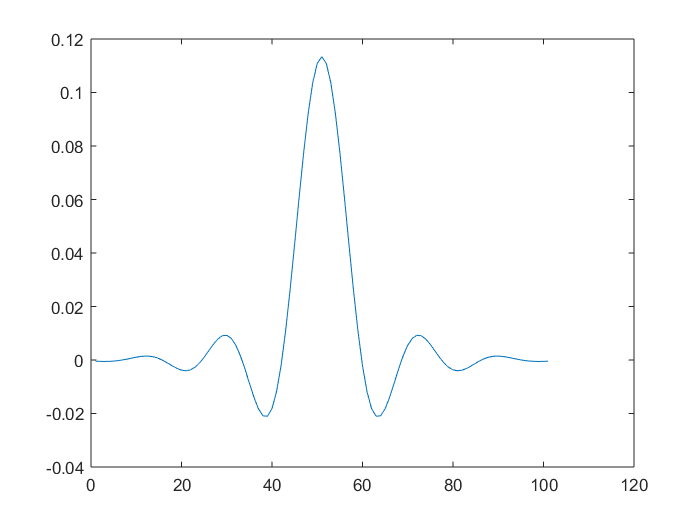

plot(h4)

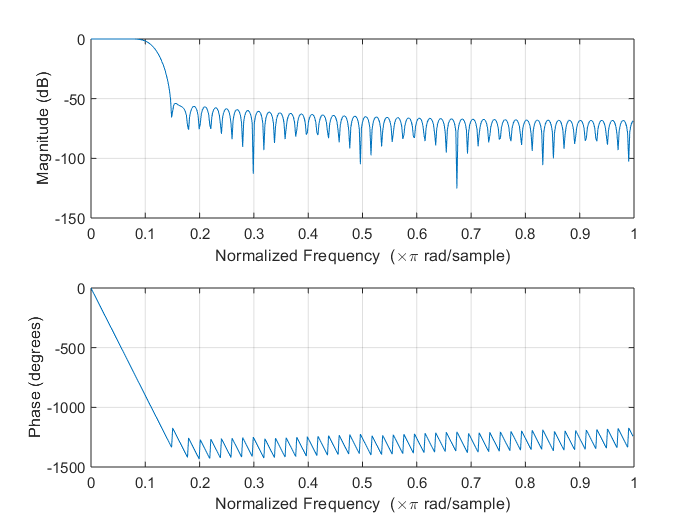

freqz(h4)

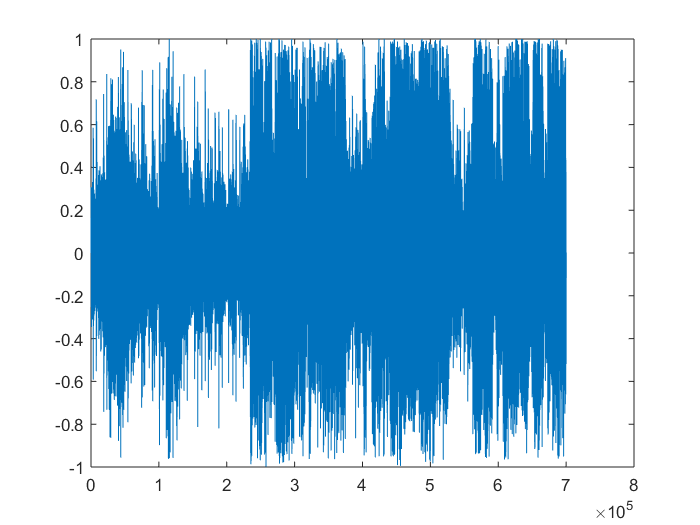

y1=cconv(y,h1);
y2=cconv(y,h2);
y3=cconv(y,h3);
y4=cconv(y,h4);
plot(y1)

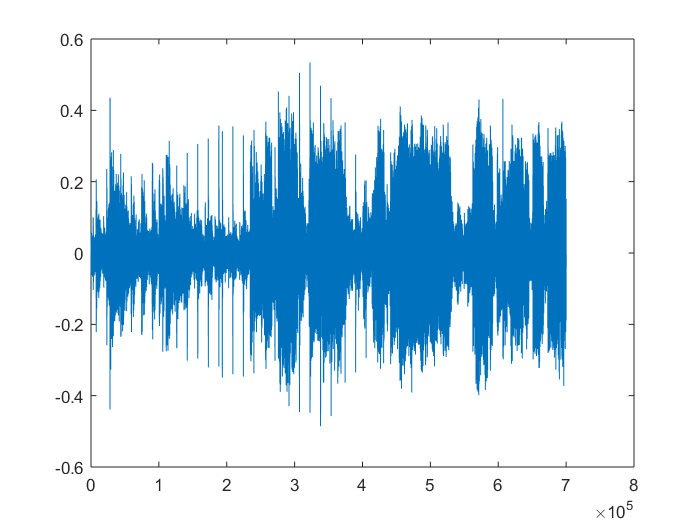

plot(y2)

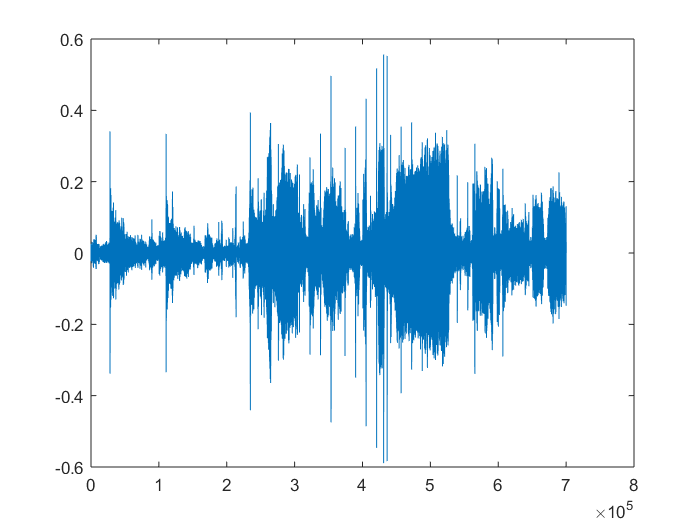

plot(y3)

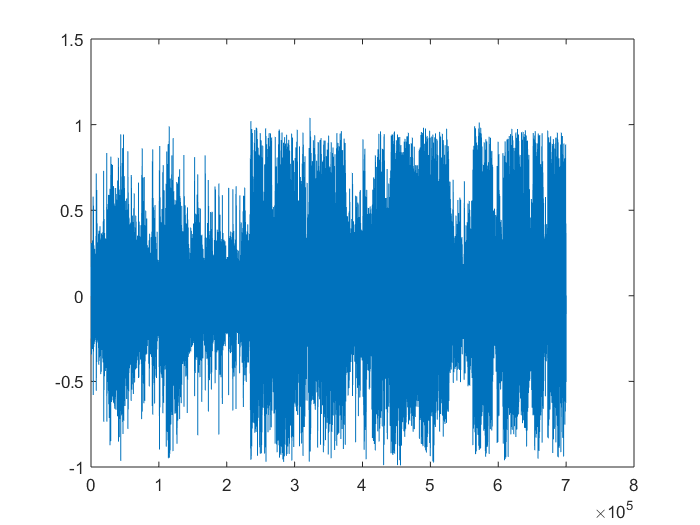

plot(y4)

y1=A1*y1;
y3=y3*A3;
y2=y2*A2;
y4=y4*A4;
de1=zeros(44100,1);
y11=[y1;de1]

y11 =     0.0253
   -0.1863
   -0.1690
   -0.2258
   -0.1947
    0.1223
    0.0154
   -0.0843
    0.1871
    0.0546


y22=[y2;de1]

y22 =     0.0003
    0.0005
    0.0008
    0.0010
    0.0013
    0.0015
    0.0017
    0.0019
    0.0020
    0.0021


y33=[y3;de1]

y33 =    -0.0488
   -0.1029
   -0.1576
   -0.2074
   -0.2465
   -0.2706
   -0.2753
   -0.2554
   -0.2072
   -0.1322


y44=[y4;de1]

y44 =    -0.0003
   -0.0006
   -0.0009
   -0.0012
   -0.0013
   -0.0012
   -0.0009
   -0.0004
    0.0003
    0.0012


yy=y11+y22+y33+y44;
sound(yy,f)
